## **Import Data**

close all; clearvars; clc
argo = load('float5903390.mat');

% Time Charts
time.anom=[107:113];
% time.window=[103:174];
time.window=[103:114]; % we fucked up
user_start=1;
user_end=106;
if user_start<user_end
    time.user=[user_start:user_end];
else
    time.user=[user_end:user_start];
end
time.all=[1:316];

% SA and PT
argo.sa=gsw_SA_from_SP(argo.salinity,argo.pressure,argo.longitude.'...
    ,argo.longitude.');
argo.pt=gsw_pt_from_t(argo.sa,argo.temperature,argo.pressure,0);

% Readable data
argo.readdt=strings(length(argo.date),1);
for i=1:length(argo.date)
    argo.readdt(i)=datestr(argo.date(i));
end
argo.readpres=argo.pressure';

## Trajectories

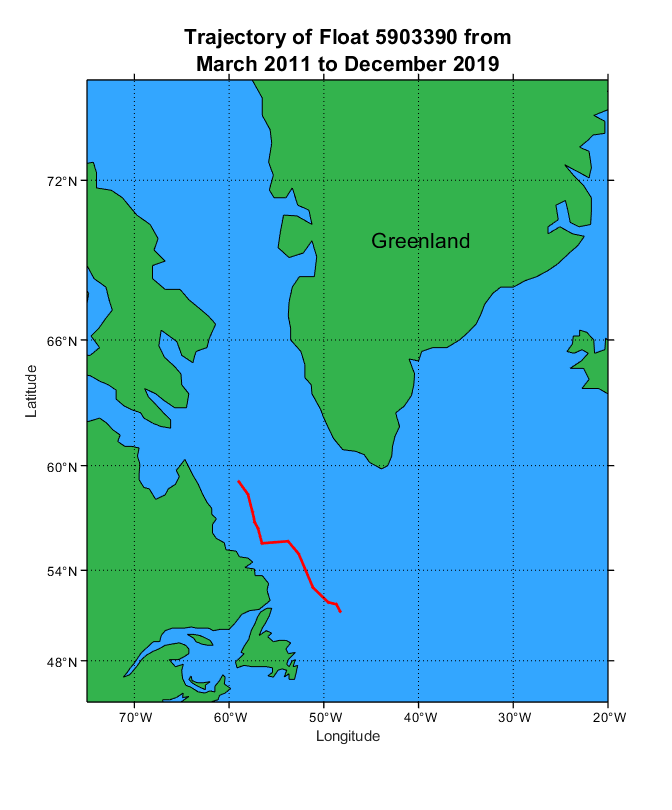

close all;
Trajectories=figure;
asd=m_proj('mercator','lat',[45 75],'long', [-75, -20]); %size of window
m_coast('patch',[.2 .7 .3],'edgecolor','k');
h=m_line(argo.longitude(time.window),argo.latitude(time.window),'marker','o','color','r','linewidth',2,...
    'markersize',1,'markerfacecolor','k');
% h=m_line(argo.longitude(time.all(1)),argo.latitude(time.all(1)),'marker','o','color','k','linewidth',2,...
%     'markersize',1,'markerfacecolor','k');
m_text(-45,70,{'Greenland'},'FontSize',16);
m_grid('tickdir','out','linewidth',1,'backcolor',[0.2,0.65,1]);
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 0.35, 0.75]);
title(['Trajectory of Float 5903390 from',newline, 'March 2011 to December 2019'],'FontSize', 16)
xlabel 'Longitude'
ylabel(['Latitude',newline])
saveas(Trajectories,'z_trajectories_all.jpg')

## Depths

top=1;
bot=794;

top_t=min(argo.pressure(argo.pressure>top));
bot_t=max(argo.pressure(argo.pressure<bot));

top_t=find(argo.pressure==top_t);
bot_t=find(argo.pressure==bot_t);
pres=[top_t:bot_t];

% argo.pressure2=argo.pressure(argo.pressure>top & argo.pressure<bot);
% argo.pt2=argo.pt([argo.pressure>top & argo.pressure<bot],:);

## PT contourf Window

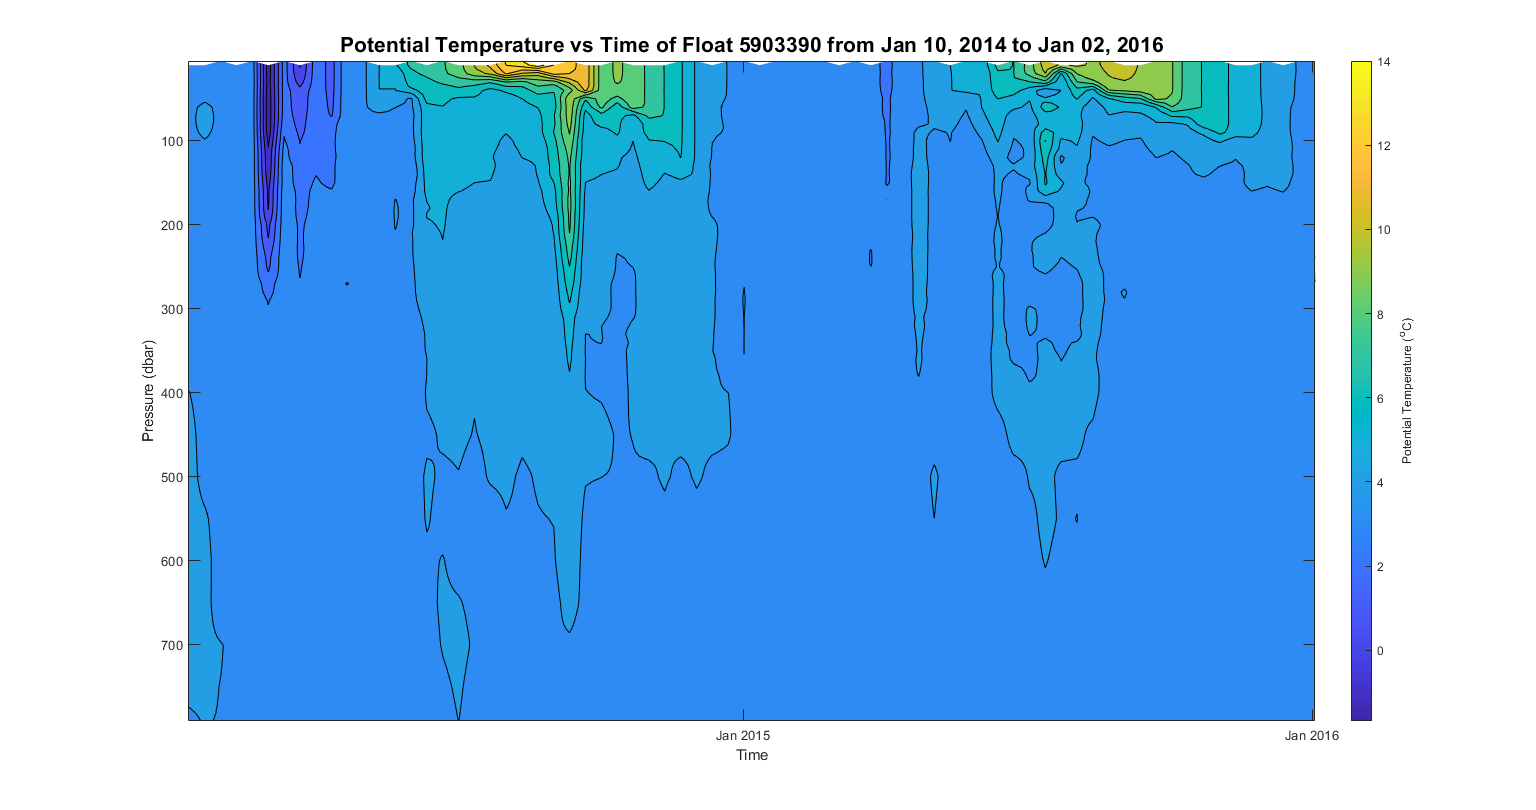

close all;
F2=figure;
contourf(argo.date(time.window),argo.pressure(pres),argo.pt(time.window,pres)','levelstep', 1)
set(gca, 'YDir','reverse')
datetick('x','mmm yyyy', 'keeplimits')
c=colorbar;
c.Label.String='Potential Temperature (^oC)';
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0.1, 0.07, 0.8, 0.75]);
% ylim(pres)
title(['Potential Temperature vs Time of Float 5903390 from ', datestr(argo.date(time.window(1)),'mmm dd, yyyy'), ' to ',...
    datestr(argo.date(time.window(end)),'mmm dd, yyyy') ],'FontSize', 16)
xlabel 'Time'
ylabel(['Pressure (dbar)'])
saveas(F2,'z_contourf_window.jpg')

## PTcolor Window

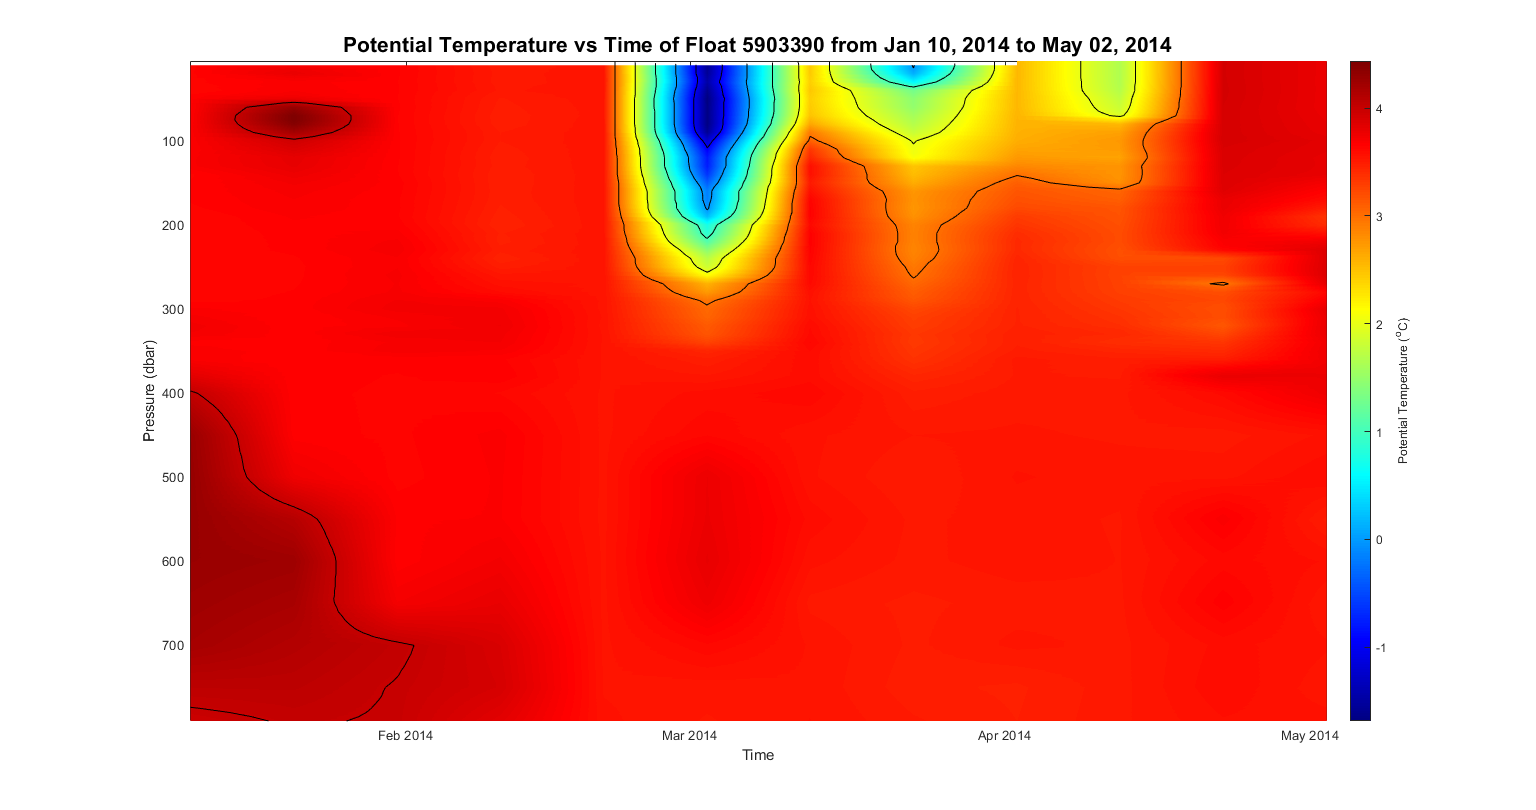

close all;
PTcolor=pcolor(argo.date(time.window),argo.pressure(pres),argo.pt(time.window,pres)');
set(gca, 'YDir','reverse')
datetick('x','mmm yyyy', 'keeplimits') 
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0.1, 0.07, 0.8, 0.75]);

% Axis Label
title(['Potential Temperature vs Time of Float 5903390 from ', datestr(argo.date(time.window(1)),'mmm dd, yyyy'), ' to ',...
    datestr(argo.date(time.window(end)),'mmm dd, yyyy') ],'FontSize', 16)
xlabel 'Time'
ylabel(['Pressure (dbar)'])

% Color bar
c=colorbar;
c.Label.String='Potential Temperature (^oC)';
%
set(PTcolor, 'EdgeColor', 'none');
PTcolor.FaceColor = 'interp';
colormap Jet;
hold on
contour(argo.date(time.window),argo.pressure(pres),argo.pt(time.window,pres)','k')
hold off

## Surfc of PT lon,lat

close all;
Surfc=figure;
argo.pressure2=repmat(argo.pressure,316,1);
argo.latitude2=repmat(argo.latitude,400,1);
argo.longitude2=repmat(argo.longitude,400,1);

% time.window=[1:316]; % this code is a lazy way to see the whole trajectory

PTsurfc=surf(argo.longitude2(pres,time.window),argo.latitude2(pres,time.window),...
    argo.pressure2(time.window,pres)',argo.pt(time.window,pres)');

Undefined function or variable 'pres'.

set(gca, 'ZDir','reverse')


c=colorbar;
c.Label.String='Potential Temperature (^oC)';
set(PTsurfc, 'EdgeColor', 'none');
colormap Jet;
PTsurfc.FaceColor = 'interp';

%
pbaspect([1 1 1])
%
xlabel 'Longitude'
ylabel('Latitude')
zlabel('Pressure (dbar)')
title(['Potential Temperature vs Position of Float 5903390 from ', datestr(argo.date(time.window(1)),'mmm dd, yyyy'), ' to ',...
    datestr(argo.date(time.window(end)),'mmm dd, yyyy') ],'FontSize', 16)

## TS Plot

Things to do:

- Axis title

- seperate out anomaly

- add isopycnals

- use jet colors

- set gcf of size

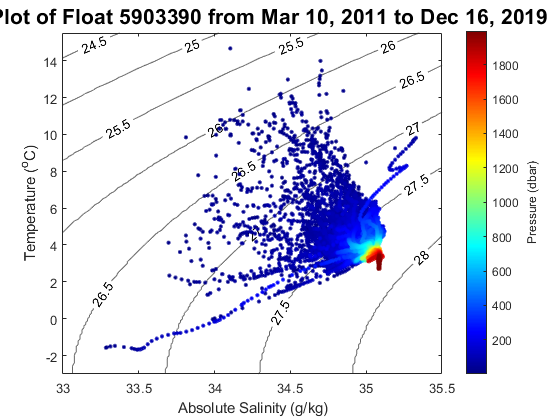

close all;
TS=figure;
% Contour lines
sx = [33:.1:35.5]; % range of salinity values 
ty = [-3:.1:15.5]; % range of temp values
[S,Trajectories] = meshgrid(sx,ty); %creates a grid we can calculate density on
PDEN = round(gsw_rho(S,Trajectories,0)-1000,2);% we subtract 1000 to look at anomaly
contour(S,Trajectories,PDEN,[24:0.5:29],'k','ShowText','on','LineColor',[0.4 0.4 0.4]) % contour plot of density
hold on
% Finish Contour lines

argo.presL=repmat(argo.pressure,316,1);

scatter(argo.sa(:),argo.pt(:),70,argo.presL(:),'.')
c=colorbar;
c.Label.String='Pressure (dbar)';
xlabel('Absolute Salinity (g/kg)')
ylabel('Temperature (^oC)')
title(['TS Plot of Float 5903390 from ', datestr(argo.date(time.all(1)),'mmm dd, yyyy'), ' to ',...
    datestr(argo.date(time.all(end)),'mmm dd, yyyy') ],'FontSize', 16)

%
colormap Jet;